# What should the basis functions be for fitting the raw lip signals?

This is similar to the tongue function (s_oeBloodFluorophoreTongue).  But the lip does not have porphyrins or keratin.

Some fluorophores are present at different tissue layers.  The superficial layers (epithelial) contain FAD and NADH in certain locations.  These are not going to be impacted by blood absorptions.  The blood is below the epithelial layer.

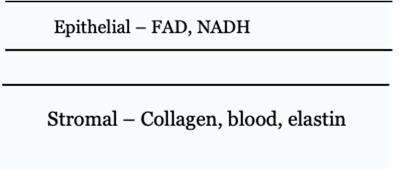

We have multiple data about the emissions of each of these fluorophores in the isetfluorescence repository.  We read them in and we also read in raw data taken from our subjects' lips.  

Each of the fluorophores has several reports in the literature.  We chose which fluorophores to use in the script s_oeFluorophoreBasis.mlx.

This script will explore how we might create basis functions to predict the raw data as weighted sums of the fluorophore excitations, but combining them as if some of the fluorophores are passing through blood.

The reason we think blood is necessary is because the raw data - directory spectral photometry measures from the tongue and lip - show some signs of the dips that are well known to be part of the blood absorbance (transmittance) measured in different contexts.

To support the calculations of absorbance and transmittance we created a Matlab class called 'medium', which helps us keep track of the relationship between absorbance, absorptance, transmittance and optical density.

## Programming notes

Repositories: isetcam, isetfluorescence and oe_tongue_lip

3/4 of the blood is oxygenated.  We might add in deoxy_ in the future.

## Initialize

Different analyses are based on different wavebands.

ieInit;
wave = 500:600;
normWave = 520;
yscale = 'linear';

## Select the fluorophores and read oxy medium

Above, we plasted all the fluorophore emissions data in a matrix (fluorophores).  We check how well the full matrix can predict the data samples.  We think it won't without accounting for blood.  

The formula is simple for the full linear calculation


$$d=\textrm{Fw}$$


We have many fluorophore files from the literature. These are analyzed in s_LoadFluorophoreEmissions.  

Apart from FAD, all of the fluorophore emission spectra decline in the wave band from 500-600nm.  They exact emissions differ between labs, but the slopes are similar.

For the lip, there is no keratin, porphyrins, or chlorophyll.  We selected which to use in the s_oeBloodFluorophoreBasis.mlx script.

% Always put the collagen in the first column

% fluorophoreNames = {'CollagenWuQu','NADH_webfluor','FADLin'};
% fluorophoreNames = {'CollagenWuQu','FADLin'};
% fluorophoreNames = {'CollagenWuQu','FADValdez'};
% fluorophoreNames = {'elastin_webfluor','FADValdez'};
% fluorophoreNames = {'collagen7','elastin_webfluor','FADValdez'};

% NADH never used in the fit
% fluorophoreNames = {'collagen1','elastin_webfluor','FAD_webfluor','NADH_webfluor'};

% fluorophoreNames = {'collagen1'};   % Interesting, but not great

% Pretty good, and better than just collagen
% fluorophoreNames = {'elastin_webfluor'};  

% Pretty good, but JEF says collagen is better
% fluorophoreNames = {'elastin_webfluor','FAD_webfluor'};

% Also very good
% fluorophoreNames = {'collagen1','FAD_webfluor'};

% Not as good
% fluorophoreNames = {'CollagenWuQu','FADValdez'};
% fluorophoreNames = {'CollagenWuQu','FAD_webfluor'};

% Just elastin is pretty much as good as collagen + elastin
% fluorophoreNames = {'elastin_webfluor','FAD_webfluor'};

% Our current favorite because we like including collagen.  But it is
% not compelled by the data.
fluorophoreNames = {'collagen1','elastin_webfluor','FAD_webfluor'};
% fluorophoreNames = {'collagen1','FAD_webfluor'};

% fluorophoreNames = {'CollagenWuQu','elastin_webfluor','FADValdez'};
[fluorophoresB,wave] = fiLoadBasis(fluorophoreNames,'wave',wave);


## Read in the oxy data

These people measured blood transmittance directly.  We used their graph, qualitatively, to select to blood optical density. It was impossible to see their numbers in detail, so we just picked a value that was approximately the right level, but we used the numerical data about oxy blood that was measured and shared in the literature.

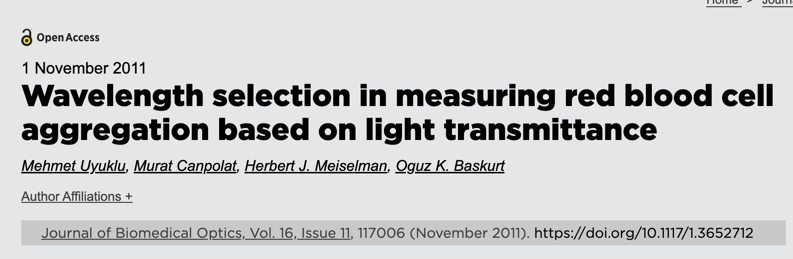

Let's amend the fluorophore basis by adding in collagen and elastin after some filtering by blood.  Notice that the blood has the two characteristic dips at 540 nm and 580nm.  We see little bumps like that in the raw data (above).

For different purposes we might choose different wavebands.  The raw data are pretty much good from 500-670 or so.  The wavelengths above 600 nm are mainly porphyrin fluorescence (bacteria on the tongue).

We only consider oxygenated blood now because 100% of the blood from the heart lung is oxygenated, and about 50% of the blood in the veins is also oxygenated. 

%{
ieFigure;
for od = (15:1:20)
    oxyblood.opticalDensity = od;
    plot(wave,oxyblood.transmittance); hold on;
end
grid on; xlabel('Wavelength (nm)'); ylabel('Transmittance');

% From the literature
bloodTransmittance = ieReadSpectra('bloodT1.mat',wave);
plot(wave,bloodTransmittance/50,'k-','LineWidth',3);
%}

## Read database

This is the database of raw measurements.

[T,dataDir] = oeDatabaseCreate;

These are measurements with different excitation lights at max intensity.  All the subjects show the peak shift from 500 to 515 as the excitation light changes from 405 to 450.

Also, notice the very large dip on the lip around 580, but not on the tongue. 

Something to remember when we write.  When you measure samples, or with an endoscope, you may be able to see different fluorophores.  The global (raw) signal, however, may be dominated by one of the fluorophores with only relatively small contributions from the others.  In this case, it appears that collagen through oxygen is the dominant signal in 500-600 band.

## 405/415 nm excitation

subjects = {'Z','B','D','J'};

% Here is oxy
% https://omlc.org/spectra/hemoglobin/summary.html
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);
odLevels = 5:1:20;
odError = zeros(numel(odLevels),numel(subjects));

disp(fluorophoreNames');

    {'collagen1'       }
    {'elastin_webfluor'}
    {'FAD_webfluor'    }



    
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405,'e level',980);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415,'e level',910);
    tongueFiles = cat(1,files405,files415);

    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);    
    wgtsNN = zeros(size(fluorophoresB,2),size(tongueData,2));

    for oo = 1:numel(odLevels)
        oxyblood.opticalDensity = odLevels(oo);
        fluorophores = oeApplyBlood(fluorophoresB,fluorophoreNames,oxyblood);
        for dd = 1:size(tongueData,2)
            wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
        end
        tmp = tongueData - fluorophores*wgtsNN;
        odError(oo,ii) = norm(tmp(:));
    end
end

% Store the od with the minimum error for each subject
[~,idx] = min(odError);
ods = odLevels(idx);

## The error at different optical density levels by subject

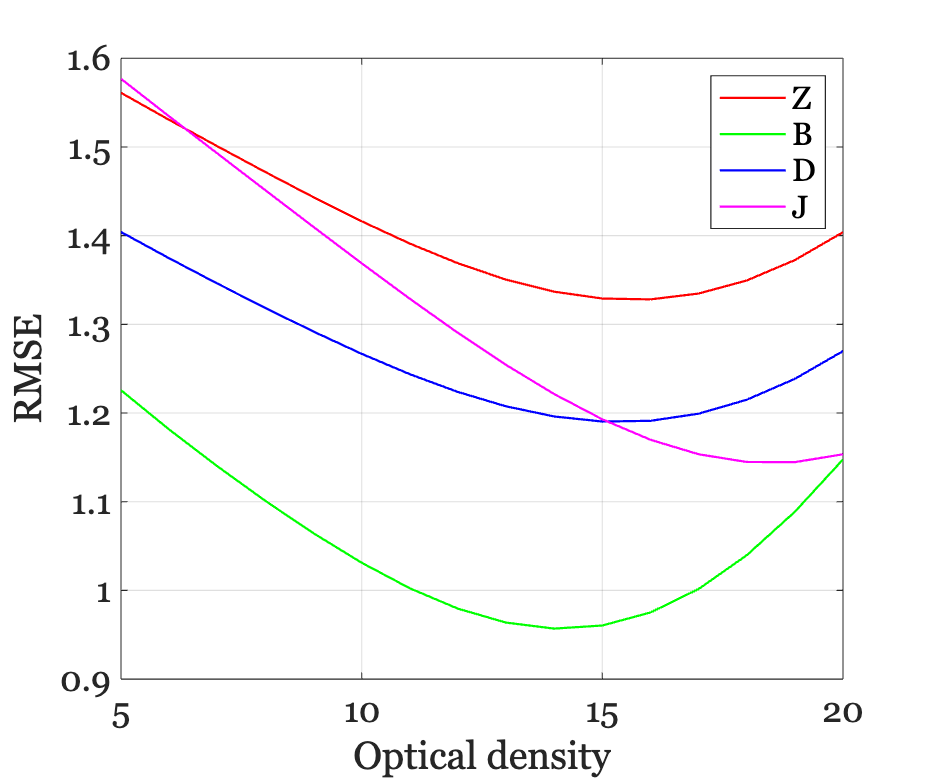

ieFigure;
plot(odLevels,odError); hold on;
% plot(idx,ods,'o');
grid on;
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## Apply the proper optical density and plot

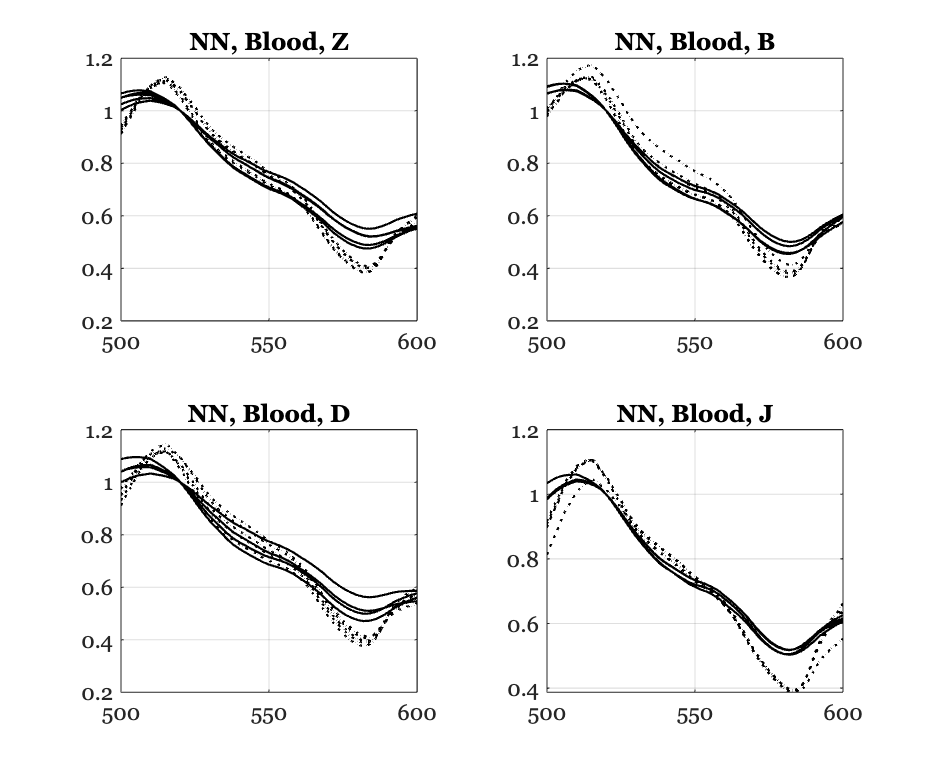

Subject Z
   15.4143   16.8672   14.6188   16.7784   14.8398
         0         0         0         0         0
    0.8772    0.8363    0.8989    0.8297    0.8810

Subject B
   15.4377   17.3797   17.0548   15.8820   14.8398
         0         0         0         0         0
    0.8189    0.7589    0.7647    0.8011    0.8810

Subject D
   17.1851   14.6275   13.0875   15.7194   14.8398
         0         0         0         0         0
    0.7989    0.8572    0.9055    0.8330    0.8810

Subject J
   20.3399   18.9798   18.8655   19.7916   14.8398
         0         0         0         0         0
    0.8604    0.8798    0.8813    0.8644    0.8810



ieFigure;
tiledlayout(2,2);

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405,'e level',980);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415,'e level',910);
    tongueFiles = cat(1,files405,files415);

    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);

    oxyblood.opticalDensity = ods(ii);
    fluorophores = oeApplyBlood(fluorophoresB,fluorophoreNames,oxyblood);
    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end
    
    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

## 450 nm excitation light

ieFigure;
tiledlayout(2,2);
disp(fluorophoreNames'); 

    {'collagen1'       }
    {'elastin_webfluor'}
    {'FAD_webfluor'    }



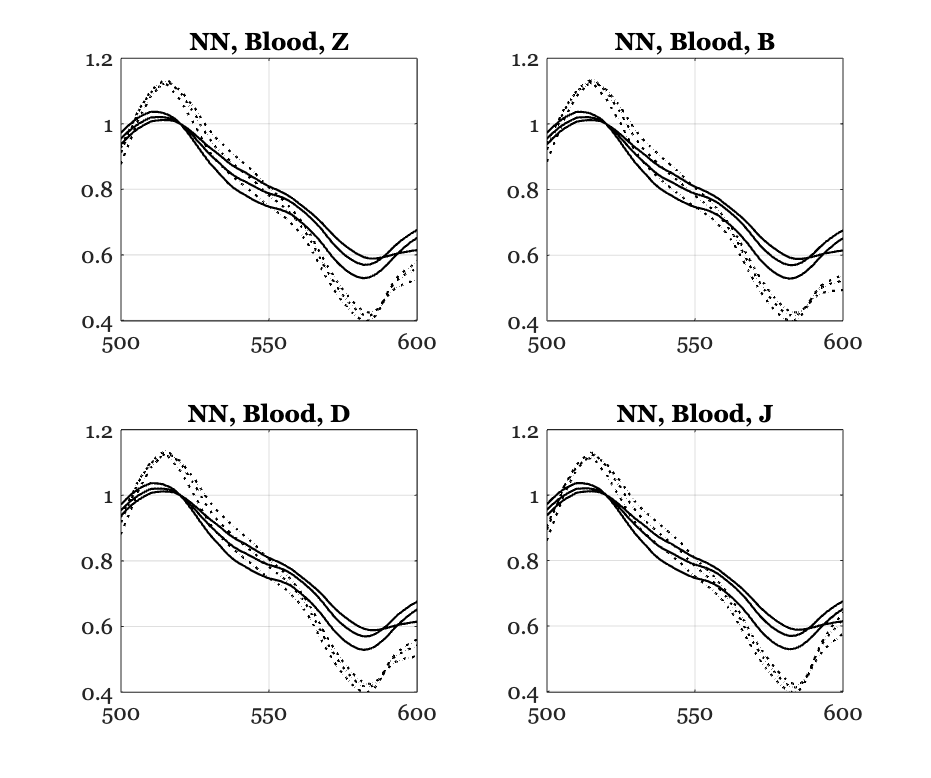

Subject Z
   12.1522   14.1624   15.6157
         0         0         0
    0.9500    0.9154    0.8706

Subject B
   10.5112   12.2463   13.6117
         0         0         0
    0.9411    0.9051    0.8577

Subject D
   11.3084   13.1773   14.5883
         0         0         0
    0.9457    0.9104    0.8643

Subject J
   14.9246   17.3986   18.9481
         0         0         0
    0.9623    0.9297    0.8881




for ii=1:numel(subjects)
    files450 = ieTableGet(T,'substrate','tongue','e wave',450,'e level',870);
    tongueData = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);    
    wgtsNN = zeros(size(fluorophores,2),size(tongueData,2));

    oxyblood.opticalDensity = ods(ii);
    fluorophores = oeApplyBlood(fluorophoresB,fluorophoreNames,oxyblood);
    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end